# 2019 Januarary emission data

Script for importing data from the following text file:

Auto-generated by MATLAB on 09-Sep-2020 12:07:20

## Importing the data

### Import emission data by month

clear;
opts = delimitedTextImportOptions("NumVariables", 26);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Var1", "FacilityName", "FacilityID", "UnitID", "Var5", "Var6", "Date", "Hour", "OperatingTime", "GrossLoadMW", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "County", "Var18", "Var19", "Var20", "Var21", "UnitType", "FuelTypePrimary", "Var24", "Var25", "Var26"];
opts.SelectedVariableNames = ["FacilityName", "FacilityID", "UnitID", "Date", "Hour", "OperatingTime", "GrossLoadMW", "County", "UnitType", "FuelTypePrimary"];
opts.VariableTypes = ["string", "categorical", "categorical", "categorical", "string", "string", "datetime", "double", "double", "double", "string", "string", "string", "string", "string", "string", "categorical", "string", "string", "string", "string", "categorical", "categorical", "string", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var5", "Var6", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var18", "Var19", "Var20", "Var21", "Var24", "Var25", "Var26"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "FacilityName", "Var5", "Var6", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "County", "Var18", "Var19", "Var20", "Var21", "UnitType", "FuelTypePrimary", "Var24", "Var25", "Var26"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Date", "InputFormat", "MM/dd/yyyy");

% Import the data
generators = readtable("D:\EERL\EPA_AMPD\emission_201901.csv", opts);
clear opts;

#### Preprocessing emission data

generators.GrossLoadMW(ismissing(generators.GrossLoadMW)) = 0;
generators

generators = 150288×10 table
    FacilityName    FacilityID    UnitID       Date       Hour    OperatingTime    GrossLoadMW       County            UnitType           FuelTypePrimary   
    ____________    __________    ______    __________    ____    _____________    ___________    ____________    __________________    ____________________

    23rd and 3rd       7910        2301     01/01/2019      0           0               0         Kings County    Combustion turbine    Pipeline Natural Gas
    23rd and 3rd       7910        2301     01/01/2019      1           0               0         Kings County    Combustion turbine    Pipeline Natural Gas
  

% test with the 01/01/2019 data only
generators_0101 = generators(generators.Date == '01/01/2019' | ismissing(generators.Date),:)

generators_0101 = 4848×10 table
    FacilityName    FacilityID    UnitID       Date       Hour    OperatingTime    GrossLoadMW       County            UnitType           FuelTypePrimary   
    ____________    __________    ______    __________    ____    _____________    ___________    ____________    __________________    ____________________

    23rd and 3rd       7910        2301     01/01/2019      0           0               0         Kings County    Combustion turbine    Pipeline Natural Gas
    23rd and 3rd       7910        2301     01/01/2019      1           0               0         Kings County    Combustion turbine    Pipeline Natural Gas

### Import RGGI to NYCA table

%% Setup the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 15);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:O184";

% Specify column names and types
opts.VariableNames = ["NYISOname", "PTID", "FacilityName", "FacilityID", "UnitID", "NYAMUnit", "Region", "UnitType", "FuelType", "AnualOperatingTime", "AnualGrossLoadMWh", "NamePlateRatingMW", "NetEnergyGWh", "FacilityLatitude", "FacilityLongitude"];
opts.VariableTypes = ["categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "double", "double", "double", "double", "double", "double"];

opts = setvaropts(opts, ["NYISOname", "FacilityName", "UnitID", "NYAMUnit", "Region", "UnitType", "FuelType"], "EmptyFieldRule", "auto");

% Import the data
RGGI2NYCA2019 = readtable("D:\EERL\EPA_AMPD\RGGI_2_NYCA_2019.xlsx", opts, "UseExcel", false);

%% Clear temporary variables
clear opts

#### Prepossesing the RGGI to NYCA reference table

RGGI2NYCA2019

RGGI2NYCA2019 = 183×15 table
           NYISOname           PTID                FacilityName                FacilityID    UnitID    NYAMUnit    Region       UnitType        FuelType      AnualOperatingTime    AnualGrossLoadMWh    NamePlateRatingMW    NetEnergyGWh    FacilityLatitude    FacilityLongitude
    _______________________    _____    ___________________________________    __________    ______    ________    ______    ______________    ___________    __________________    _________________    _________________    ______

generator_combiner = RGGI2NYCA2019(:, ["NYISOname", "PTID", "FacilityName", "FacilityID", "UnitID", "NYAMUnit", "Region", "UnitType", "FuelType"]);
generator_combiner_NYAM = generator_combiner(generator_combiner.NYAMUnit ~= 'NA',:)

generator_combiner_NYAM = 171×9 table
           NYISOname           PTID                FacilityName                FacilityID    UnitID    NYAMUnit    Region       UnitType        FuelType  
    _______________________    _____    ___________________________________    __________    ______    ________    ______    ______________    ___________

    Indeck-Yerkes              23781    Indeck-Yerkes Energy Center              50451       1          A2F-CC      A2F      Combined cycle    Natural gas
    Lockport                   23791    Lockport                                 54041       11854      A2F-CC      A2F      Combined cycle    Natural gas
    Lockport                   2379

NYISO_names = unique(generator_combiner_NYAM.NYISOname);
PTIDs = unique(generator_combiner_NYAM.PTID);
unit_types = unique(generator_combiner_NYAM.UnitType);
fuel_types = unique(generator_combiner_NYAM.FuelType);
NYAM_units = unique(generator_combiner_NYAM.NYAMUnit);

#### Group summary of generators

groupsummary(generator_combiner_NYAM, "NYAMUnit")

ans = 8×2 table
    NYAMUnit    GroupCount
    ________    __________

     A2F-CC         37    
     A2F-ST         11    
     GHI-ST          8    
     J-CC           13    
     J-CT           42    
     J-ST           12    
     K-CT           40    
     K-ST            8    


groupsummary(RGGI2NYCA2019, ["UnitType", "FuelType"] , ["mean", "sum"], "NamePlateRatingMW")

ans = 8×5 table
         UnitType          FuelType      GroupCount    mean_NamePlateRatingMW    sum_NamePlateRatingMW
    __________________    ___________    __________    ______________________    _____________________

    Combined cycle        Natural gas        59                307.69                    18154        
    Combustion turbine    Fuel Oil           12                56.792                    681.5        
    Combustion turbine    Natural gas        73                45.984                   3356.8        
    Steam Turbine         Coal                3                325.87                    977.6        
    Steam Turbine         Fuel Oil           13                521.12                   6774.6        
    Steam Turbine         Natural gas        18                292.13                   5258

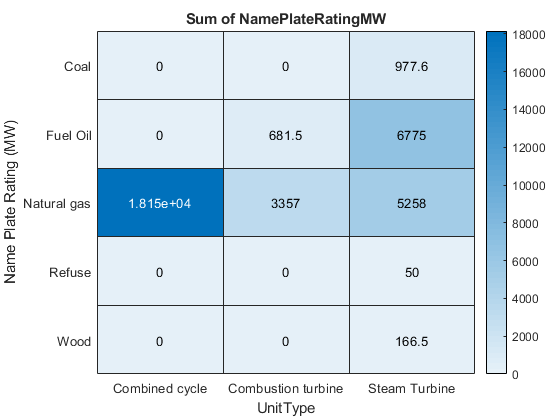

heatmap(RGGI2NYCA2019, "UnitType", "FuelType", "ColorVariable", "NamePlateRatingMW", "ColorMethod","sum")
ylabel("Name Plate Rating (MW)")

#### Distribution of name plate rating by unit type, fuel type, and associate NYAM units

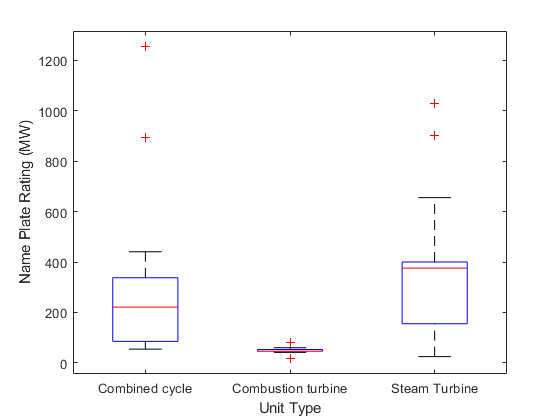

boxplot(RGGI2NYCA2019.NamePlateRatingMW, RGGI2NYCA2019.UnitType)
xlabel("Unit Type")
ylabel("Name Plate Rating (MW)")

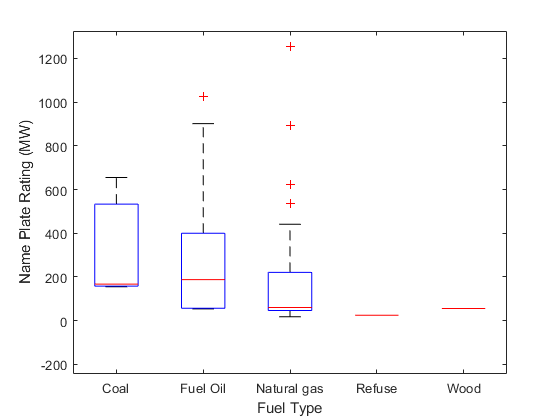

boxplot(RGGI2NYCA2019.NamePlateRatingMW, RGGI2NYCA2019.FuelType)
xlabel("Fuel Type")
ylabel("Name Plate Rating (MW)")

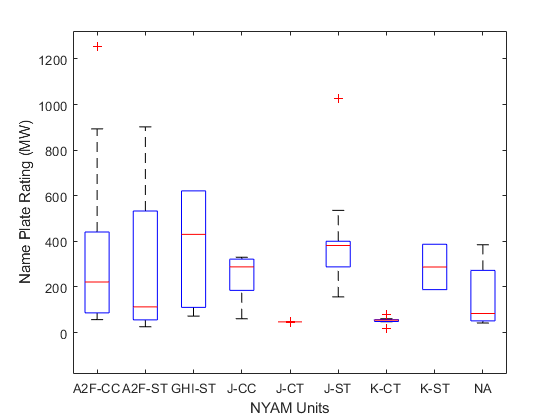

boxplot(RGGI2NYCA2019.NamePlateRatingMW, RGGI2NYCA2019.NYAMUnit)
xlabel("NYAM Units")
ylabel("Name Plate Rating (MW)")

### Join the emission table and the reference table

% Join tables
generator_joint = outerjoin(generators_0101,generator_combiner_NYAM,'Type','right',...
    'Keys',{'FacilityName','FacilityID','UnitID'},'MergeKeys',true)

generator_joint = 4104×16 table
    FacilityName    FacilityID    UnitID       Date       Hour    OperatingTime    GrossLoadMW       County       UnitType_generators_0101      FuelTypePrimary       NYISOname    PTID     NYAMUnit    Region    UnitType_generator_combiner_NYAM     FuelType  
    ____________    __________    ______    __________    ____    _____________    ___________    ____________    ________________________    ____________________    _________    _____    ________    ______

### Subsetting the generators with NYAM Units

A2F_CC = generator_joint(generator_joint.NYAMUnit == "A2F-CC", :);
J_CC = generator_joint(generator_joint.NYAMUnit == "J-CC", :);
J_CT = generator_joint(generator_joint.NYAMUnit == "J-CT", :);
K_CT = generator_joint(generator_joint.NYAMUnit == "K-CT", :);
A2F_ST = generator_joint(generator_joint.NYAMUnit == "A2F-ST", :);
GHI_ST = generator_joint(generator_joint.NYAMUnit == "GHI-ST", :);
J_ST = generator_joint(generator_joint.NYAMUnit == "J-ST", :);
K_ST = generator_joint(generator_joint.NYAMUnit == "K-ST", :);

A2F_CC_hourly = groupsummary(A2F_CC, ["Date", "Hour"], "sum", "GrossLoadMW")

A2F_CC_hourly = 24×4 table
       Date       Hour    GroupCount    sum_GrossLoadMW
    __________    ____    __________    _______________

    01/01/2019      0         37              208      
    01/01/2019      1         37              116      
    01/01/2019      2         37              115      
    01/01/2019      3         37              117      
    01/01/2019      4         37              116      
    01/01/2019      5         37              147      
    01/01/2019      6         37              376      
    01/01/2019      7         37              520      
    01/01/2019      8         37              525      
    01/01/2019      9         37              601      
    01/01/2019     10         37              702      
    01/01/2019     11         37              714      
    01/01/2019     12         37              711   

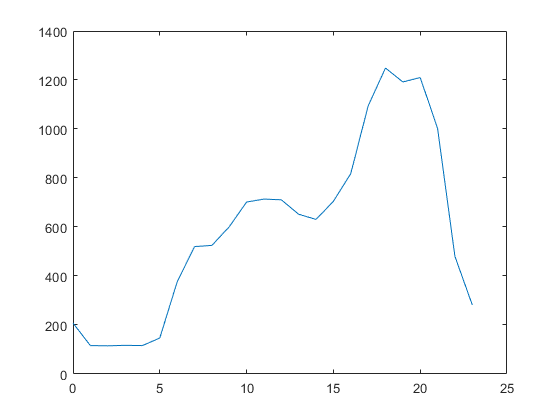

plot(A2F_CC_hourly.Hour, A2F_CC_hourly.sum_GrossLoadMW)

### Calculating max power, min power, and ramp rate

A2F_CC_P_max = max(A2F_CC_hourly.sum_GrossLoadMW)

A2F_CC_P_max =         1249


A2F_CC_P_min = min(A2F_CC_hourly.sum_GrossLoadMW)

A2F_CC_P_min =    115


A2F_CC_ramprate = A2F_CC_hourly.sum_GrossLoadMW(2:end) - A2F_CC_hourly.sum_GrossLoadMW(1:end-1);
A2F_CC_ramprate = [A2F_CC_ramprate; 0];
A2F_CC_hourly.RampRate = A2F_CC_ramprate;
A2F_CC_hourly

A2F_CC_hourly = 24×5 table
       Date       Hour    GroupCount    sum_GrossLoadMW    RampRate
    __________    ____    __________    _______________    ________

    01/01/2019      0         37              208            -92   
    01/01/2019      1         37              116             -1   
    01/01/2019      2         37              115              2   
    01/01/2019      3         37              117             -1   
    01/01/2019      4         37              116             31   
    01/01/2019      5         37              147            229   
    01/01/2019      6         37              376            144   
    01/01/2019      7         37              520              5   
    01/01/2019      8         37              525             76   
    01/01/2019      9         37              601     

A2F_CC_RampUp_max = max(A2F_CC_hourly.RampRate)

A2F_CC_RampUp_max =    276


A2F_CC_RampDown_max = min(A2F_CC_hourly.RampRate)

A2F_CC_RampDown_max =   -523


[P_max, P_min, RampUp_max, RampDown_max] = GenAggregator(J_CT)

P_max = 24×5 table
       Date       Hour    GroupCount    sum_GrossLoadMW    RampRate
    __________    ____    __________    _______________    ________

    01/01/2019      0         42               0              0    
    01/01/2019      1         42               0              0    
    01/01/2019      2         42               0              0    
    01/01/2019      3         42               0              0    
    01/01/2019      4         42               0              0    
    01/01/2019      5         42               0              0    
    01/01/2019      6         42               0              0    
    01/01/2019      7         42               0              0    
    01/01/2019      8         42               0              0    
    01/01/2019      9         42               0              

P_min =      0


RampUp_max =      0


RampDown_max =      0


% Join tables
month_joint = outerjoin(generators,generator_combiner_NYAM,'Type','right',...
    'Keys',{'FacilityName','FacilityID','UnitID'},'MergeKeys',true)

month_joint = 127224×16 table
    FacilityName    FacilityID    UnitID       Date       Hour    OperatingTime    GrossLoadMW       County       UnitType_generators      FuelTypePrimary       NYISOname    PTID     NYAMUnit    Region    UnitType_generator_combiner_NYAM     FuelType  
    ____________    __________    ______    __________    ____    _____________    ___________    ____________    ___________________    ____________________    _________    _____    ________    ______    <s

A2F_CC_month = month_joint(month_joint.NYAMUnit == "A2F-CC", :)

A2F_CC_month = 27528×16 table
          FacilityName          FacilityID    UnitID       Date       Hour    OperatingTime    GrossLoadMW        County         UnitType_generators      FuelTypePrimary       NYISOname    PTID     NYAMUnit    Region    UnitType_generator_combiner_NYAM     FuelType  
    ________________________    __________    ______    __________    ____    _____________    ___________    _______________    ___________________    ____________________    _________    _____    ________   

[P_max, P_min, RampUp_max, RampDown_max] = GenAggregator(A2F_CC_month)

gen_hourly = 744×5 table
       Date       Hour    GroupCount    sum_GrossLoadMW    RampRate
    __________    ____    __________    _______________    ________

    01/01/2019      0         37              208            -92   
    01/01/2019      1         37              116             -1   
    01/01/2019      2         37              115              2   
    01/01/2019      3         37              117             -1   
    01/01/2019      4         37              116             31   
    01/01/2019      5         37              147            229   
    01/01/2019      6         37              376            144   
    01/01/2019      7         37              520              5   
    01/01/2019      8         37              525             76   
    01/01/2019      9         37              601       

P_max =         3420


P_min =    115


RampUp_max =    708


RampDown_max =   -875
